# CCS 2017b 3. Gyak - előben

s = tf('s');
H = (s^2 + 1) / ( (s^2 + 2*s + 5) * (s + 1) )


H =
 
         s^2 + 1
  ---------------------
  s^3 + 3 s^2 + 7 s + 5
 
Continuous-time transfer function.



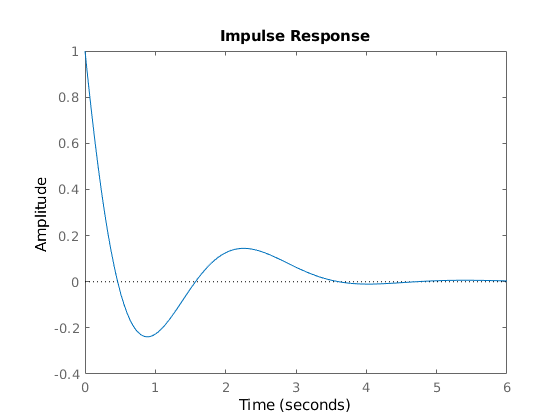

figure, impulse(H)

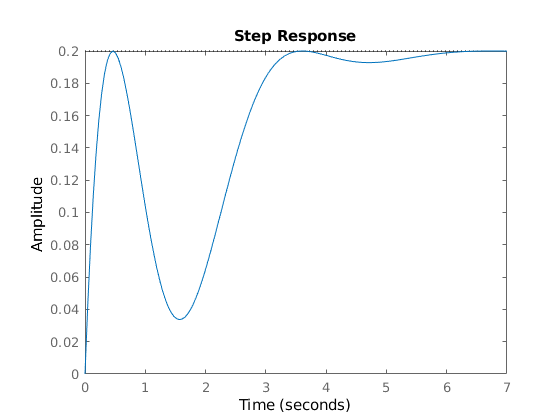

figure, step(H)

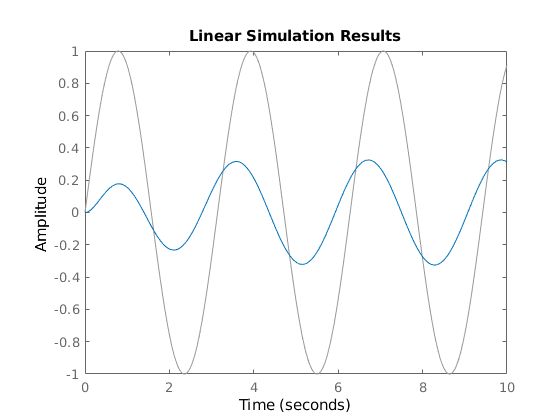

t = linspace(0,10,1000);
u = sin(2*t);
lsim(H,u,t)

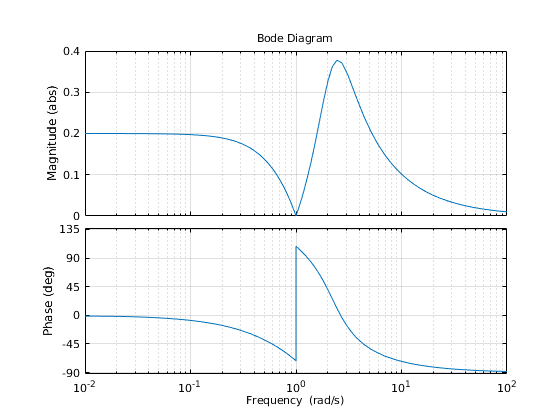

opts = bodeoptions;
opts.MagUnits = 'abs';
bodeplot(H,opts), grid on